# Ex04. Introduction to Signals and systems

### s1320112/ Motohisa YAMANO

## 1.1. Plot 3 pairs of Fourier Transform

This report illustrates three pairs of Fourier Transform pairs corresponding to a = 0.1, 0.5, and 1.0. For numerical computation, the time domain t and frequency domain ω are sampled at intervals of 0.01 (from -10 to 10) and 0.1 (from -100 to 100), respectively. The resulting waveforms are organized into a 3 * 2 subplot grid for comparative analysis.

#### 1.1.1 MATLAB Code

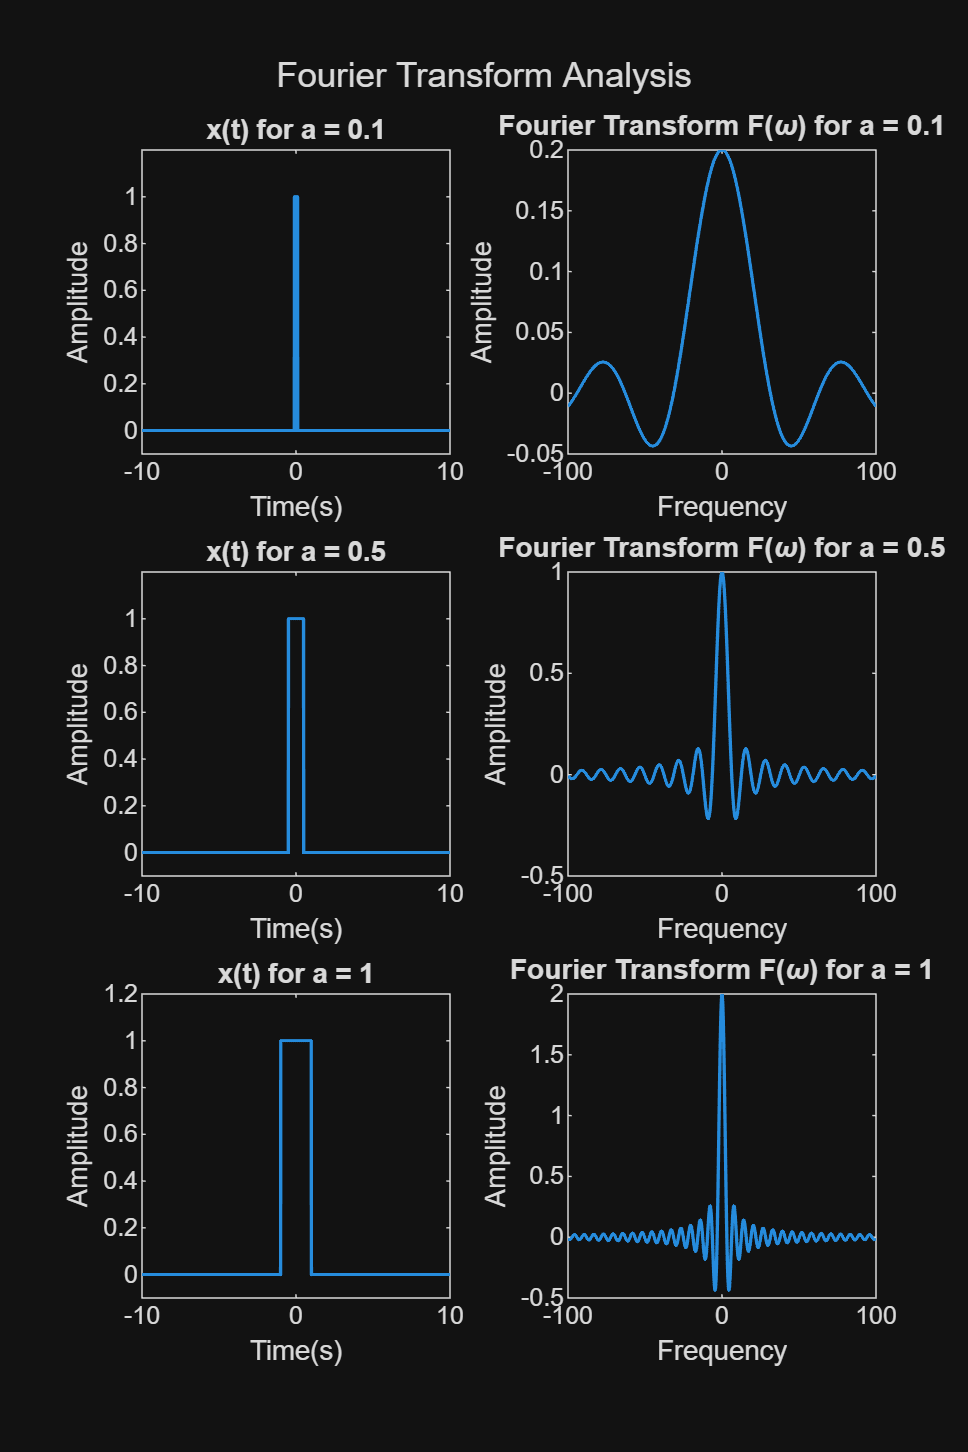

t = -10:0.01:10;
omega = -100:0.1:100;
alpha = [0.1, 0.5, 1.0];
x = @(t, a) (abs(t) < a);
ft = @(omega, a) 2*a*sinc((omega * a) / pi);

%% In the Math Problem section, I evaluate that the Fourier Transform of
%% x(t) is just (2*a*sin(omega * a))/(omega * a). However, according to the
%% officail documentation("https://jp.mathworks.com/help/signal/ref/sinc.html#mw_e3c5bb46-ffb8-4805-9512-17c003c986c7"), 
%% the final angle in sinc() is equal to the product of pi and the radius.
%% So that I divided the argument by pi. 

cnt = 1;

figure('Position', [100, 100, 600, 900]);
for idx=alpha
    subplot(3, 2, cnt); % Select the first subplot
    p1 = plot(t, x(t,idx),'LineWidth', 1.2); % Plot the Fourier transform for the given 'a'
    xlabel("Time(s)");
    ylabel("Amplitude");
    ylim([-0.1, 1.2])
    title(['x(t) for a = ', num2str(idx)]);
    cnt = cnt + 1; % Increment counter for the next subplot

    subplot(3, 2, cnt); % Select the first subplot
    p2 = plot(omega, ft(omega, idx),'LineWidth', 1.2); % Plot the Fourier transform for the given 'a'
    xlabel("Frequency");
    ylabel("Amplitude");
    title(['Fourier Transform F(\omega) for a = ', num2str(idx)]);
    cnt = cnt + 1; % Increment counter for the next subplot
end
sgtitle('Fourier Transform Analysis'); 

#### 1.1.2 Discussion

 The Fourier Transform charts shown above indicate several key features.

 First of all, as the variable *a* increases, the width of the rectangular pulse *x(t)* in the time domain becomes wider. Conversely, the width of the main lobe in the Fourier Transform *X(ω)* becomes narrower, and its oscillations occur more rapidly. Furthermore, the peak value of *X(ω)* at *ω = 0* increases proportionally, which is exactly equal to twice the variable *a* (*2a*). From this result, it is evident that there is a inverse relationship between the time and frequency domains in terms of signal width. 

 Theoretically, if we expand this to the condition where *a* approaches infinity (*a → +∞*), the time-domain signal *x(t)* would become a constant DC signal of 1. Correspondingly, the peak of *X(ω)* at *ω = 0* would approach infinity, and its values at *ω ≠ 0* would converge to 0. This perfectly illustrates that *X(ω)* approaches an impulse function. 

## 1.2 Math Problem

Below is the snapshot of my answer in fill-blank math problem.